clc
clear all

1. Set the cfg.model_dir field to the path to the toolkit directory, and then add the "common" folder to your MATLAB path

% Add path to relevant functions
cfg.model_dir = '/Shared/boeslab/Users/jcgriffis/mlsm_code_repo/model_code/';
addpath(genpath(fullfile(cfg.model_dir,'common')));
addpath(fullfile(cfg.model_dir, 'stacked_models'));

2. Specify the stacked model analysis parameters in a new cfg structure

% Set up cfg
cfg.parallel = 1; % Use parallel processing
cfg.model_spec = 'mean'; % choose the meta model
cfg.modality = 'other'; % non-lesion analysis
cfg.optimize_hyperparams = 1; % Optimize hyper-parameters
cfg.cross_validation = 1; % Do cross-validation
cfg.fit_explanatory_model = 0; % Don't fit an explaantory model

% Get default cfg for specified settings
cfg = get_default_stack_cfg(cfg);

MATLAB parallel processing functionality detected; parallel processing enabled



% Modify defaults for relevant options
cfg.parallel = 1; % Use parallel processing

% Permutation testing
cfg.cv.permutation = 1;
cfg.cv.n_perm = 20;

% Define output directory
cfg.out_dir = '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/test/stacked_example';

3. Specify the paths to the results files for the models that you want to stack as entries in a cell array

% Analysis parameters
cfg.model_paths = ["/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/results/plsr_mae_token_lesion_d1",...
"/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/results/plsr_mae_token_connectome_d0",...
"/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/results/plsr_mae_token_flnm_d0"]

cfg = struct with fields:
                model_dir: '/Shared/boeslab/Users/jcgriffis/mlsm_code_repo/model_code/'
                 parallel: 1
               model_spec: 'mean'
                 modality: 'other'
     optimize_hyperparams: 1
         cross_validation: 1
    fit_explanatory_model: 0
                    cat_Y: 0
               use_scores: 1
                confounds: []
              standardize: 0
                strat_var: []
                   hp_opt: [1×1 struct]
                       cv: [1×1 struct]
                  out_dir: '/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/test/stacked_example'
              model_paths: ["/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/results/plsr_mae_token_lesion_d1"    "/Shared/boeslab/Users/jcgriffis/toolkit_paper_analyses/results/plsr_mae_token_connectome_d0"    …    ]


% Run the model stacking analysis, supplying the model_paths cell array and cfg struct as inputs. 
[stacked_results, base_results] = run_model_stacking(cfg);

Preallocating CV results
Outer CV repeats:1/5
Outer CV repeats:2/5
Outer CV repeats:3/5
Outer CV repeats:4/5
Outer CV repeats:5/5
Full-sample Cross-Validation Correlation Test: r=0.63214, p=7.1921e-33
Preallocating CV results
Outer CV repeats:1/5
Outer CV repeats:2/5
Outer CV repeats:3/5
Outer CV repeats:4/5
Outer CV repeats:5/5
Preallocating CV results
Outer CV repeats:1/5
Outer CV repeats:2/5
Outer CV repeats:3/5
Outer CV repeats:4/5
Outer CV repeats:5/5
Preallocating CV results
Outer CV repeats:1/5
Outer CV repeats:2/5
Outer CV repeats:3/5
Outer CV repeats:4/5
Outer CV repeats:5/5
Preallocating CV results
Outer CV repeats:1/5
Outer CV repeats:2/5
Outer CV repeats:3/5
Outer CV repeats:4/5
Outer CV repeats:5/5
Preallocating CV results
Outer CV repeats:1/5
Outer CV repeats:2/5
Outer CV repeats:3/5
Outer CV repeats:4/5
Outer CV repeats:5/5
Preallocating CV results
Outer CV repeats:1/5
Outer CV repeats:2/5
Outer CV repeats:3/5
Outer CV repeats:4/5
Outer CV repeats:5/5
Preallocating CV re

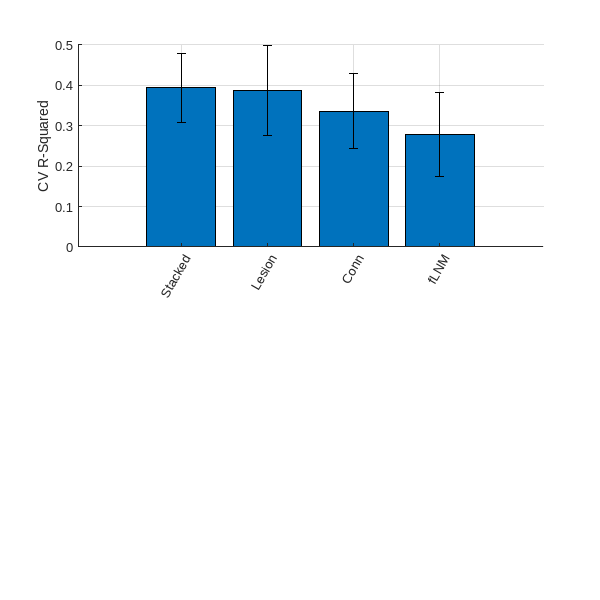

% Plot mean and SD model results

clf;

% Get result matrix
result_matrix = zeros(size(stacked_results.mse,1).^2, length(cfg.model_paths)+1);
result_matrix(:,1) = stacked_results.r2_ss(:);
model_names = cell(length(cfg.model_paths)+1,1);
model_names{1} = 'Stacked';
for i = 1:length(cfg.model_paths)
    result_matrix(:,i+1)= base_results.r2_ss{i}(:);
    [~, name] = fileparts(cfg.model_paths{i});
    model_names{i+1} = name(16:end-3);
end
subplot(2,1,1)
bar(mean(result_matrix,1));
hold on;
errorbar(mean(result_matrix,1), std(result_matrix, [], 1), 'LineStyle', 'none', 'Color', 'k')
set(gca, 'XtickLabel', model_names);
ylabel('CV R-Squared')
set(gca, 'XtickLabel', {'Stacked', 'Lesion', 'Conn', 'fLNM'})
set(gca, 'XtickLabelRotation', 60);
set(gcf, 'position', [0, 0, 600, 600]); box off; grid on;